# Finite differences for the wave equation

Implementation of a simple numerical schemes for the wave equation.


$$\frac{\partial^2 u}{\partial t^2} = c^2 \frac{\partial^2 u}{\partial x^2}.$$


Applying the second-order centered differences to approximate the derivatives,


$$\frac{u_j^{n+1} - 2 u_j^n + u_j^{n-1}}{\Delta t^2} = c^2 \frac{u^n_{j+1} - 2 u_j^n + u^n_{j-1}}{\Delta x^2}.$$


It can be arrange to obtain


$$u_j^{n+1} = s (u_{j+1}^n + u_{j-1}^n) + 2(1-s)u_j^n - u_{j}^{n-1},$$


where


$$s = c^2 \frac{\Delta t^2}{\Delta x^2}.$$


It is known that the scheme needs to satisfy  $s \le 1$ for stability. Copyright 2015-2016 The MathWorks, Inc.

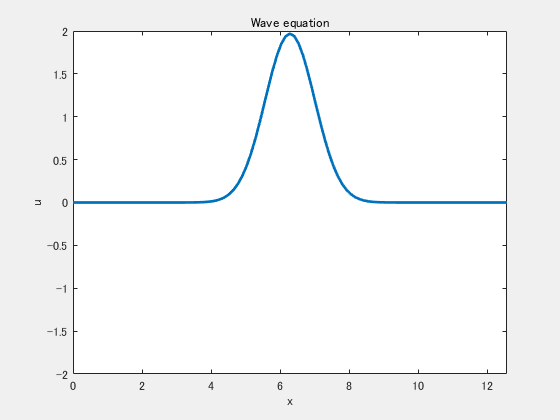

## Problem Setup

N = 101;
L = 4*pi;
x = linspace(0,L,N);

% It has three data set; 1: past, 2: current, 3: future.
u = zeros(N,3);
s = 0.5;

## Initial Condition

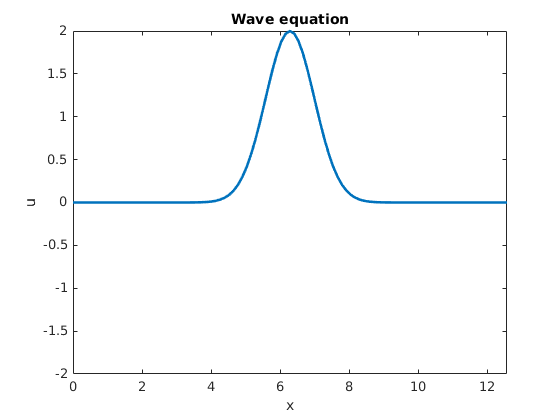

% Gaussian Pulse
y = 2*exp(-(x-L/2).^2);
u(:,1) = y;
u(:,2) = y;

% Plot the initial condition.
handle_line = plot(x,u(:,2),'LineWidth',2);
axis([0,L,-2,2]);
xlabel('x'); ylabel('u');
title('Wave equation');

## Boundary condition

% Dirichet Boundary conditions
u(1,:) = 0;
u(end,:) = 0;

## Simulation

at ii= 1


at ii= 2


at ii= 3


at ii= 4


at ii= 5


at ii= 6


at ii= 7


at ii= 8


at ii= 9


at ii= 10


at ii= 11


at ii= 12


at ii= 13


at ii= 14


at ii= 15


at ii= 16


at ii= 17


at ii= 18


at ii= 19


at ii= 20


at ii= 21


at ii= 22


at ii= 23


at ii= 24


at ii= 25


at ii= 26


at ii= 27


at ii= 28


at ii= 29


at ii= 30


at ii= 31


at ii= 32


at ii= 33


at ii= 34


at ii= 35


at ii= 36


at ii= 37


at ii= 38


at ii= 39


at ii= 40


at ii= 41


at ii= 42


at ii= 43


at ii= 44


at ii= 45


at ii= 46


at ii= 47


at ii= 48


at ii= 49


at ii= 50


at ii= 51


at ii= 52


at ii= 53


at ii= 54


at ii= 55


at ii= 56


at ii= 57


at ii= 58


at ii= 59


at ii= 60


at ii= 61


at ii= 62


at ii= 63


at ii= 64


at ii= 65


at ii= 66


at ii= 67


at ii= 68


at ii= 69


at ii= 70


at ii= 71


at ii= 72


at ii= 73


at ii= 74


at ii= 75


at ii= 76


at ii= 77


at ii= 78


at ii= 79


at ii= 80


at ii= 81


at ii= 82


at ii= 83


at ii= 84


at ii= 85


at ii= 86


at ii= 87


at ii= 88


at ii= 89


at ii= 90


at ii= 91


at ii= 92


at ii= 93


at ii= 94


at ii= 95


at ii= 96


at ii= 97


at ii= 98


at ii= 99


at ii= 100


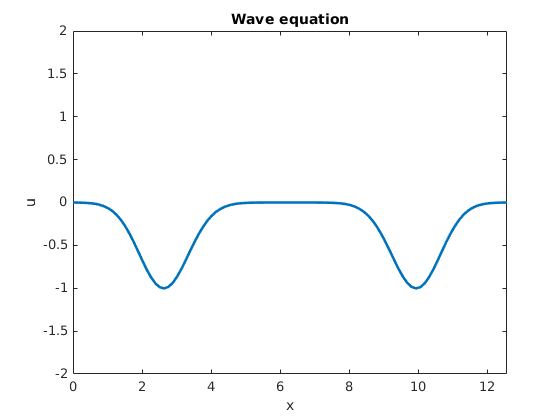

filename = 'wave.gif';
for ii=1:100
    disp(['at ii= ', num2str(ii)]);
    u(2:end-1,3) = s*(u(3:end,2)+u(1:end-2,2)) ...
        + 2*(1-s)*u(2:end-1,2) ...
        - u(2:end-1,1);
    u(:,1) = u(:,2);
    u(:,2) = u(:,3);
    handle_line.YData = u(:,2);
    drawnow;
    frame = getframe(gcf);
    im = frame2im(frame);
    [A,map] = rgb2ind(im,256);
    if ii==1
           imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',0.05);
    else
        imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.05);
    end
end